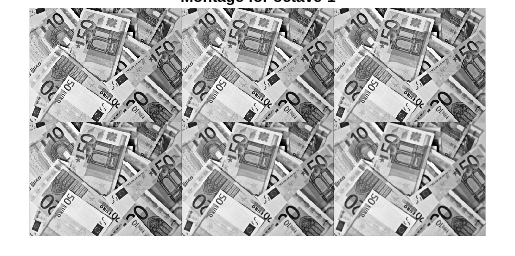

% Read input image and generate gaussian and Dog_pyramids with sift operator 
clc %clear console
clear %clear workspace
close all hidden %close all windows

pic = imread('fh_3dimgprocessing/4. Exercises/3. SIFT Detector/img_test.jpg');

data = sift_operator(pic);

data = data.gauss_and_dog_pyramid();

montage(data.gauss_p(1:6,1)), title("Montage for octave-1")

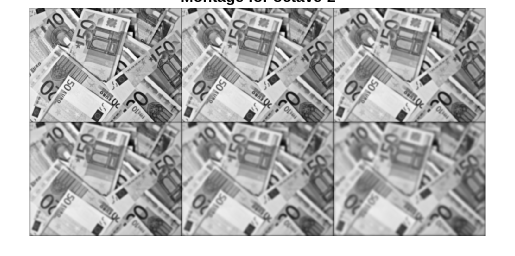

montage(data.gauss_p(1:6,2)), title("Montage for octave-2")

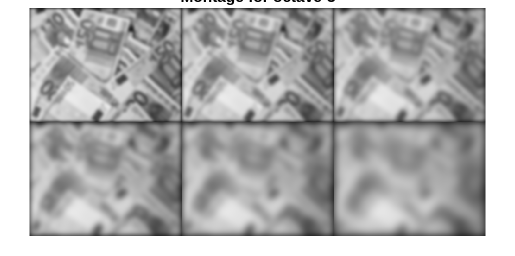

montage(data.gauss_p(1:6,3)), title("Montage for octave-3")

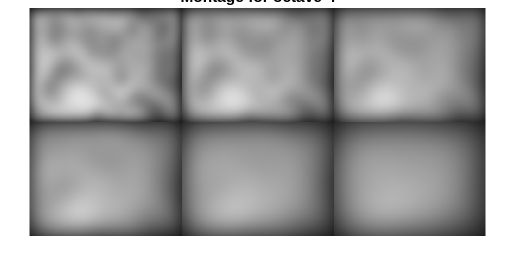

montage(data.gauss_p(1:6,4)), title("Montage for octave-4")

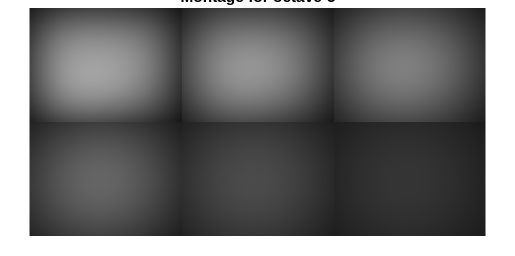

montage(data.gauss_p(1:6,5)), title("Montage for octave-5")

% Keypoint detection and Identification 
keypoints = sift_keypoints(data);
keypoints = keypoints.find_all_keypoints();

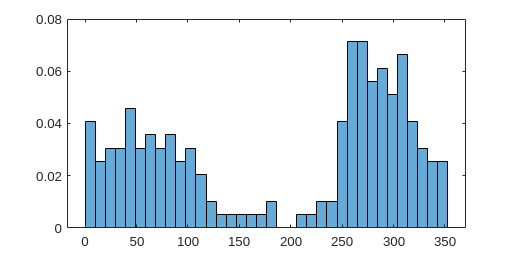

% Find and determine the orientation histogram  
test_qualifier = sift_orientation(keypoints);
test_qualifier = test_qualifier.find_gradient();
test_qualifier = test_qualifier.find_histogram();

% PLot size and orientation of keypoints in image
figure;
imshow(pic)

hold on
n_keypoints  = test_qualifier.keypoints.counter

n_keypoints = 4251

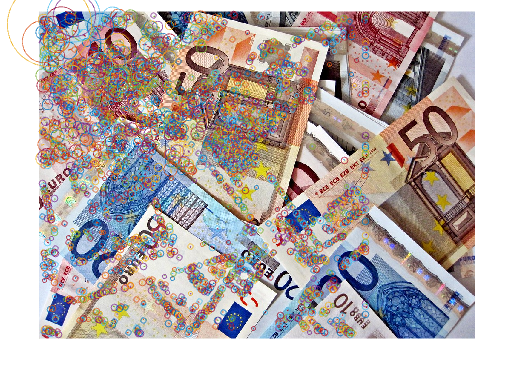


for i = 1:n_keypoints
    if test_qualifier.scale(i,1) > 0
        plot(test_qualifier.keypoints.positions(i,4),test_qualifier.keypoints.positions(i,5),'o',"MarkerSize",(test_qualifier.scale(i,1)*2.5));
        hold on 

        u = test_qualifier.scale(i,1)*2.5*cos(test_qualifier.orientation(i,3));
        v = test_qualifier.scale(i,1)*2.5*sin(test_qualifier.orientation(i,3));
        quiver(test_qualifier.keypoints.positions(i,4),test_qualifier.keypoints.positions(i,5),u,v);
        hold on

    end 
end

hold off

%siftkeypoints = detectSIFTFeatures(rgb2gray(pic))

siftkeypoints =   4314×1 SIFTPoints array with properties:

          Scale: [4314×1 single]
    Orientation: [4314×1 single]
         Octave: [4314×1 int32]
          Layer: [4314×1 int32]
       Location: [4314×2 single]
         Metric: [4314×1 single]
          Count: 4314


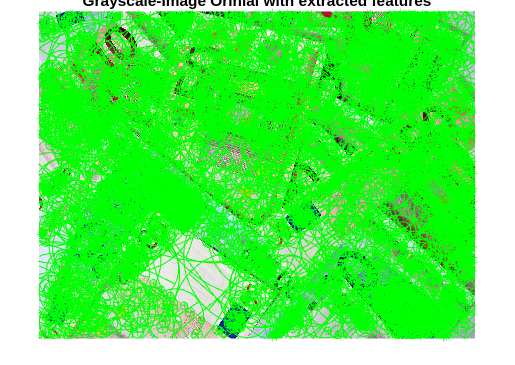


%[featuresOriginal,validPtsOriginal] = extractFeatures(rgb2gray(pic),siftkeypoints);
%figure;
%imshow(pic);
%hold on;
%plot(validPtsOriginal,showOrientation=true);
%title("Grayscale-Image Orinial with extracted features")